# Create and Customize Surface Plots

Surf plots are three-dimensional plots that look like a fish-net shaped lattice of horizontal and vertical lines that are draped over a surface. The surface color varies according to the data in the Z direction.

### Generate Membrane Matrix

A 2-D array is necessary for plotting a surface. To generate a known function, the membrane command can be used which returns a 2-D array of a membrane eigenfunction in a specified size.

L = 100*membrane(1,25);

### Basic Surface Plot

Surf plots are three-dimensional plots that look like a fish-net shaped lattice of horizontal and vertical lines that are draped over a surface. 

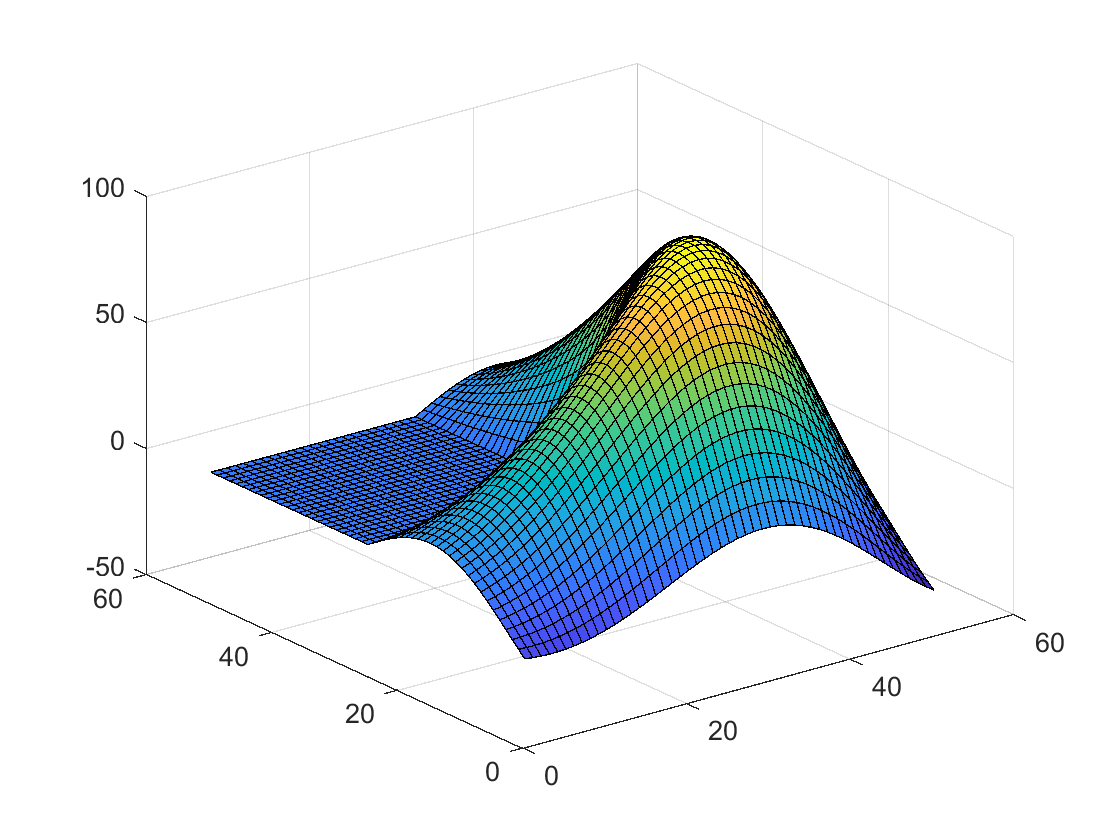

surf(L);

## Customizing Surface Plots

### Specify the Colormap and Lighting

Customize the color pattern of the mesh plot by specifying the built-in colormap it references. A colormap scales a color gradient between the lowest and heighest $Z$ value providing improved contour and magnitude visualization. Additionally, lighting parameters are used to determine the brightess of the colormap in certain areas. The Lighting location and the lighting algorithm can be customized to offer varying appearances.

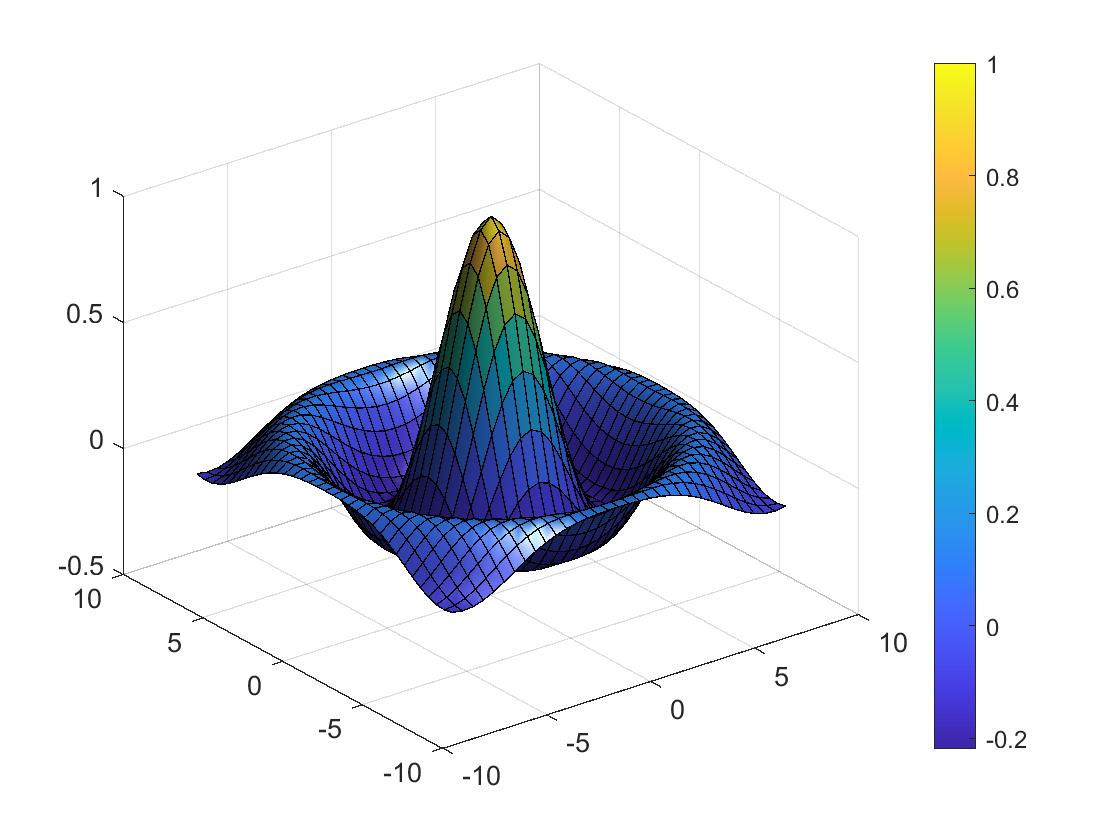

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;

surf(X,Y,Z)
camlight
lighting gouraud;           % Specify lighting algorithm
colormap parula;           % Specify the colormap
colorbar                                 % Add a color bar legend

### Modify the Surface Appearance 

Create a semitransparent mesh surface by specifying the* FaceAlpha *property name-value pair with a value less than 1. To make the surface more transparent, specify the *EdgeColor *as none which will eliminate the *x*-*y *lines.

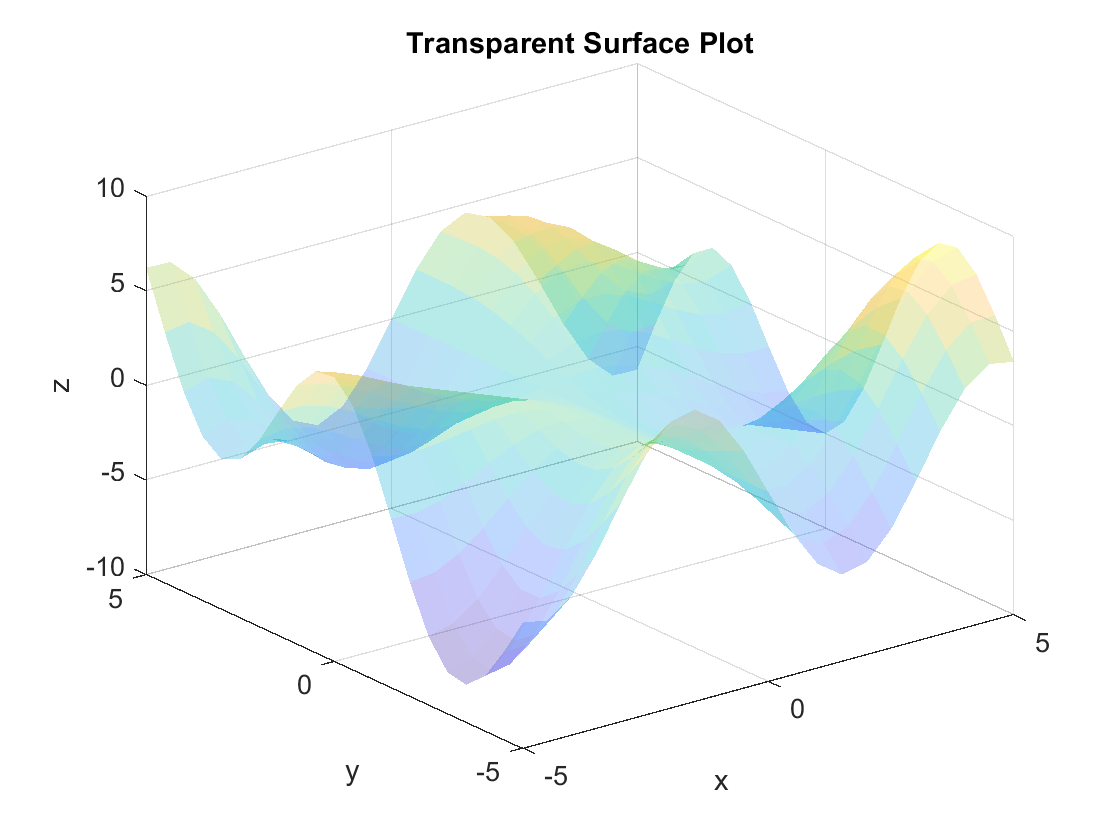

[X,Y] = meshgrid(-5:.5:5);
Z = Y.*sin(X) - X.*cos(Y);

faceColorType = "flat";
faceAlpha = 0.3;
sf = surf(X,Y,Z,...
    'FaceAlpha',faceAlpha,...                         % Specify the surface transparency
    "FaceColor", faceColorType,...                    % Specify the surface color pattern
    "EdgeColor","none");                              % remove the edges

title("Transparent Surface Plot")
xlabel('x')
ylabel('y')
zlabel('z')

## **Get All Surf Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a surf, uncomment the following code

% get(sf)

### Additional Information

Follow the link below to go to the documentation page to learn about the plot type in detail.

[surf](https://www.mathworks.com/help/matlab/ref/surf.html)